# 和と積分の関係

## 確率と確率密度 (一般論)

### 確率と確率密度の関係

離散的な確率変数 $x_i$ の出現確率を $p_i$ とする．

$x_i$ が準連続的なスペクトルを成す場合，$x_i$ の値を微小な区間 $\Delta x$ に見出す確率を $p(x)\Delta x$ と書いて確率密度 $p(x)$ を導入することができる．

また微小区間 $\Delta x$ に含まれる離散的な値 $x_i$ の個数を $\rho(x)\Delta x$ と書いて “状態数密度” $\rho(x)$ を定義すると，位置 $x=x_i$ の周りの区間 $\Delta x$ に含まれる $\rho(x)\Delta x$ 個の値は近似的に等確率 $p_i$ で現れるから，確率 $p_i$ と確率密度 $p(x)$ は


$$p(x)\Delta x=p_i\rho(x)\Delta x
,\qquad \therefore
p(x)=p_i\rho(x)$$


で関係付けられる．

### 確率の規格化

確率 $p_i$ の規格化条件は $\displaystyle \sum_i p_i=1$ である．

左辺の和を2段階でとることを考えよう．

まず幅 $\Delta x$ に含まれる “状態” にわたる確率の和は，上記のように確率 $p_i$ と “状態数”  $\rho(x)\Delta x$ の積として近似的に


$$p_i\rho(x)\Delta x=p(x)\Delta x
$$


と表される．

次いでこの表式を全ての区間 $\Delta x$ について足し上げれば，すべての状態 $x_i$ にわたって確率の和をとったことになる．

よって全確率は


$$\sum_i p_i
\quad \to \quad
\int p(x)\mathrm{d}x$$


のように積分に置き換わり，確率密度も (理想的には) $\int p(x)\mathrm{d}x=1$と規格化されていることになる．

和を積分に置き換える規則としてまとめると


$$\sum_i \quad \to \quad \int \mathrm{d}x\rho(x)$$


である．

## コイン投げの問題

コイン投げの問題における確率 $P_{\mathrm{d}}$ と確率密度 $P_{\mathrm{c}}$ の関係を検証する．**(以下，モデルの詳細な説明はひとまず省略する．)**

$\eta$ の出現確率 


$$P_{\mathrm{d}}(N,\eta)=\frac{1}{2^N}{}_N\mathrm{C}_X$$


(ただし $\eta=\frac{2X}{N}-1$) に上記の一般論


$$P_{\mathrm{c}}(N,\eta)=\rho(\eta)P_{\mathrm{d}}(N,\eta)
,\qquad
\rho(\eta)=\frac{N}{2}$$


を適用して得た確率密度 $y_1=P_{\mathrm{c}}(N,\eta)$ を，$|\eta|\ll 1$ における確率密度の近似式


$$y_2=\sqrt{\frac{N}{2\pi}}e^{-\frac{N}{2}\eta^2}$$


と比較する．

$y_1$と $y_2$ のグラフはよく一致している．

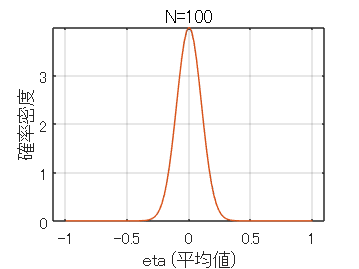

N = 100;% コインの枚数

p = 0.5;% 表が出る確率

x = 0:N;
y = binopdf(x, N, p);% P_d
eta = (2*x/N) - 1;

y1 = (N/2) * y;
y2 = sqrt(N/2/pi) * exp(-(N/2)*(eta.*eta));

figure;
%bar((x-N*p)/N,N*y,1)
%bar(x,y,1)
plot(eta, y1, eta, y2)

title(strcat('N= ',int2str(N)));
xlabel("eta (平均値)");
ylabel("確率密度");
xlim([-1.1 1.1])
ylim([0 Inf])
grid on

## 簡単な実例 (正規分布)

histgramを使うと自動的にビンの幅が設定される．

度数分布の縦軸は出現回数であり，これをデータ数で割ると確率になり，さらに冒頭の一般論において $\rho(x)=1/(\mathrm{BinWidth})$ なので，これをビンの幅で割ると確率密度になる：

(確率密度)=(度数分布)÷(データ数)÷(ビンの幅)．

これに基づき具体的な乱数データについて確率密度を数値的に計算し，確率密度の解析的な表現とプロットを比較しよう．

以下では標準正規分布に従う乱数について，出現確率の分布 (確率密度) を描画する．

数値データーと解析的な曲線はよく合っている．

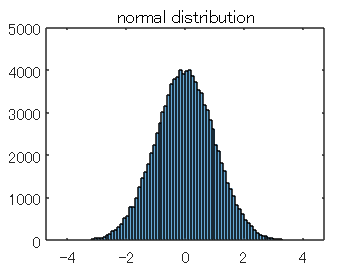

N = 100000;
data = randn([1 N]);
h = histogram(data);
title('normal distribution')

d = h.Values;
x = h.BinEdges(1:end-1)+0.5*h.BinWidth;

y1 = d / N / h.BinWidth;
y2 = normpdf(x)

y2 =     0.0000    0.0001    0.0001    0.0002    0.0002    0.0004    0.0005    0.0007    0.0010    0.0015    0.0020    0.0028    0.0038    0.0051    0.0069    0.0091    0.0119    0.0154    0.0198    0.0252    0.0317    0.0396    0.0488    0.0596    0.0721    0.0863    0.1023    0.1200    0.1394    0.1604    0.1826    0.2059    0.2299    0.2541    0.2780    0.3011    0.3230    0.3429    0.3605    0.3752    0.3867    0.3945    0.3984    0.3984    0.3945    0.3867    0.3752    0.3605    0.3429    0.3230


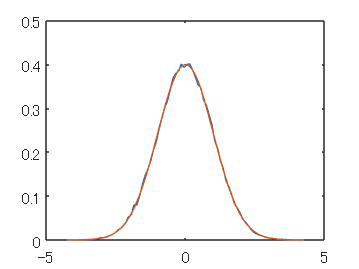

plot(x, y1, x, y2)

## 和と積分 (関連・参考)

### Fourier級数展開とFourier積分

多変数 $\vec{x}=(x_1,\cdots,x_N)$ の周期関数 $f(\vec{x})$ (各変数 $x_i$ の周期 $L$) は


$$f(\vec{x})=\sum_{\vec{k}}c_{\vec{k}}e^{i\vec{k}\cdot \vec{x}}
,\qquad
c_{\vec{k}}=\frac{1}{L^N}\int f(\vec{x})e^{-i\vec{k}\cdot \vec{x}}\mathrm{d}^Nx$$


となる．

ただし $\vec{k}=\frac{2\pi}{L}\vec{n}$ は整数の組 $\vec{n}=(n_1,\cdots,n_N)$ に応じて定まる“波数”ベクトルであり，また展開係数の式における積分は各変数 $x_i$ の1周期 $-L/2\le x_i\le L/2$ にわたって行う．

ここで周期 $L\to \infty$ の極限をとると，Fourier積分の公式へと導かれる．

実際このとき離散的な“波数”   $\vec{k}$ は連続的なスペクトルに移行し，1つの状態 $\vec{k}$ が“波数空間”に占める“体積” $\Delta^N k=(2\pi/L)^N$ はゼロに近づく．

すると展開係数


$$c_{\vec{k}}=\frac{1}{L^N}\int f(\vec{x})e^{-i\vec{k}\cdot \vec{x}}\mathrm{d}^Nx \to \frac{\mathrm{d}^Nk}{(2\pi)^N}f(\vec{k}),\qquad f(\vec{k})\equiv \int f(\vec{x})e^{-i\vec{k}\cdot \vec{x}}\mathrm{d}^Nx$$


から波数空間の体積要素 $\mathrm{d}^Nk$ がくくり出されて


$$\begin{array}{cc|c|c} f(\vec{x})= & \displaystyle \sum_{\vec{k}} & c_{\vec{k}} & e^{i\vec{k}\cdot \vec{x}} \\ & \downarrow & \downarrow & \downarrow \\ f(\vec{x})= & \displaystyle \int & \displaystyle \frac{\mathrm{d}^Nk}{(2\pi)^N}f(\vec{k}) & e^{i\vec{k}\cdot \vec{x}} \end{array}$$


とFourier積分に移行する．

なお $f(\vec{k})$ の積分範囲 $-L/2\le x_i\le L/2$ はこの極限 $L\to \infty$ で $\vec{x}$ 空間全体となっている．

以上の説明から理解されるように，

(1) 一般にFourier成分 $f(\vec{k})$ はFourier係数 $c_{\vec{k}}$ と次元が異なる：

 
$$[c_{\vec{k}}]=[f(\vec{x})],\qquad [f(\vec{k})]=\frac{[c_{\vec{k}}]}{[\mathrm{d}^Nk]}=[f(\vec{x})][L]^N.$$


(2) Fourier積分を


$$f(\vec{x})\simeq \sum_{\Delta^Nk} \frac{\Delta^Nk}{(2\pi/L)^N} c_{\vec{k}}e^{i\vec{k}\cdot \vec{x}}$$


と書けば，これはもとのFourier級数展開における因子 $c_{\vec{k}}e^{i\vec{k}\cdot \vec{x}}$ に波数空間の体積要素 $\Delta^Nk$ 内の離散的な状態 $\vec{k}$ の数 $\frac{\Delta^Nk}{(2\pi/L)^N}$ をかけ，全ての要素 $\Delta^Nk$ について和をとったものになっており，平面波の重ね合わせと見ることができる．

(3) $L^N=V$ とおき，和を積分に置き換える規則として書くと


$$\frac{1}{V}\sum_{\vec{k}}\to \int \frac{\mathrm{d}^Nk}{(2\pi)^N}.$$


### 点状の粒子系の密度

質点に対する式から連続体に対する式に移るには

- 質点の質量 $m$　→　体積要素 $\mathrm{d}V$ 内の質量 $\rho \mathrm{d}V$, 

- 質点についての和 $\sum$　→　物体の全体積にわたる積分 $\int$

とすれば良い ($\rho$は質量密度)．

逆に連続体に対する式から離散的な点に対する式に戻るには，粒子の系に対する質量密度の表式


$$\rho(\vec{r},t)=\sum_a m_a\delta(\vec{r}-\vec{r}_a(t))$$


を用いれば良い．

例えば慣性モーメント・テンソルについて

- 質点系 $I_{ik}=\sum m(x_l^2\delta_{ik}-x_ix_k)$

- 連続体 $I_{ik}=\int \mathrm{d}V \rho (x_l^2\delta_{ik}-x_ix_k)$

### Huygensの原理

スクリーンの開口部を通る光が観測点Pに作る場 (電場または磁場の任意の成分) を考える．

開口部分を覆う面の，面積素ベクトル $\mathrm{d}\vec{f}$ を持つ面積素における場 $u$ が距離 $R$ 隔たる点Pに作る場は $au\frac{e^{ikR}}{R}\mathrm{d}f_n$ と書ける．

ここに $\mathrm{d}f_n$ は光源から面積素に向かう方向単位ベクトルを $\vec{n}$ として $\mathrm{d}f_n=\mathrm{d}\vec{f}\cdot \vec{n}$ である．

以上より点Pの場は開口にわたる積分


$$u_{\mathrm{P}}=a\int \frac{ue^{ikR}}{R}\mathrm{d}f_n$$


で表される．

同様に考えれば，複数の点光源が観測点Pに作る場は


$$u_{\mathrm{P}}=a\sum \frac{ue^{ikR}}{R}$$


という形をとる．

上式の積分とは $a$ の次元が異なることに注意する．

### 積分は「f(x)dxの和」

積分 $I=\int f(x)\mathrm{d}x$は「$f(x)$の和」ではなく，正確には「$f(x)\mathrm{d}x$の和」である．

「$f(x)$の和」と「$f(x)\mathrm{d}x$の和」では一般に，物理量としての次元が異なる．

あらゆる $x$ に対する $f(x)$ が積分 $I$ に寄与していると言うことはできる．

例えばFeynmanの経路積分


$$K(x_2,t_2;x_1,t_2)=\int_{x_1}^{x_2} \mathcal{D}[x(t)]e^{iS[x(t)]/\hbar}$$


は粗く言えば，すべての可能な経路からの $e^{iS/\hbar}$ の和であるが，正確にはすべての可能な経路に関する $e^{iS/\hbar}$ が遷移振幅 $K$ に寄与しているのであって，これは“ある種の”和である．

## TeXの入力について

\bm, \varDelta, \hphantom,環境(align,matrixなど)は使えない．